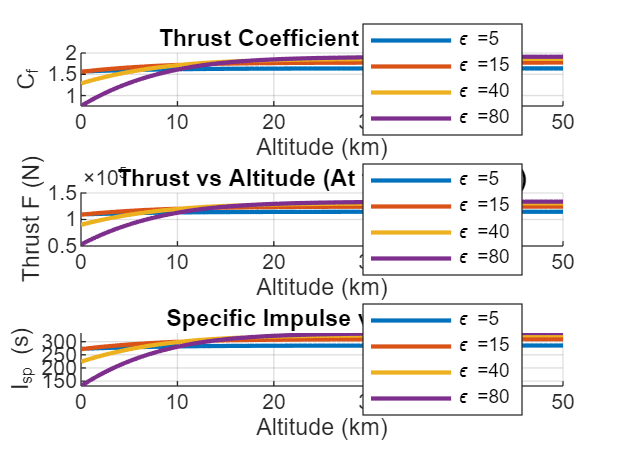

%% Rocket Nozzle Expansion Ratio Calculator (version-safe Live Script)
% Compares thrust F, thrust coefficient Cf, and Isp vs altitude for one or
% more expansion ratios ε = Ae/At. No toolboxes; uses numeric sweep for Me.

%% 1) Propellant & chamber conditions (edit these)
gamma = 1.22;            % specific heat ratio (e.g., ~1.22 LOX/RP-1, ~1.20-1.25 typical)
R     = 355;             % J/(kg·K) effective gas const (R = R_u/Mw)
Tc    = 3500;            % K   chamber temperature
Pc    = 7e6;             % Pa  chamber pressure (e.g., 70 bar)
At    = 0.01;            % m^2 throat area (scale factor)
g0    = 9.80665;         % m/s^2

% Expansion ratios to compare
eps_list = [5, 15, 40, 80];   % try a few nozzles

%% 2) Altitude sweep (0 → 50 km)
h_vec = (0:500:50000)';        % meters
Pa_vec = zeros(size(h_vec));
for i=1:numel(h_vec)
    Pa_vec(i) = stdAtm_P(h_vec(i));  % Pa (ambient)
end

%% 3) Preallocate result arrays
Nalt = numel(h_vec);
Neps = numel(eps_list);
Cf   = zeros(Nalt,Neps);
F    = zeros(Nalt,Neps);
Isp  = zeros(Nalt,Neps);

%% 4) Core physics helpers (anonymous)
Pr_exit  = @(Me) (1 + (gamma-1)/2 * Me.^2).^(-gamma/(gamma-1));             % Pe/Pc
Tr_exit  = @(Me) (1 + (gamma-1)/2 * Me.^2).^(-1);                            % Te/Tc
AoverAt  = @(Me) (1./Me) .* ((2/(gamma+1) .* (1 + (gamma-1)/2 .* Me.^2)).^((gamma+1)/(2*(gamma-1))));
mdot_ch  = Pc*At/sqrt(Tc) * sqrt(gamma/R) * (2/(gamma+1))^((gamma+1)/(2*(gamma-1)));  % choked m_dot

%% 5) Loop: for each epsilon and altitude, compute Me, Pe, Te, Ve, then F, Cf, Isp
for j=1:Neps
    eps = eps_list(j);
    % Create a coarse supersonic Mach grid and pick Me giving A/A* ~ eps
    Me_grid = linspace(1.01, 10, 5000);
    [~, idxMe] = min(abs(AoverAt(Me_grid) - eps));
    Me = Me_grid(idxMe);  % fixed by geometry
    
    Pe_over_Pc = Pr_exit(Me);
    Te_over_Tc = Tr_exit(Me);
    
    for i=1:Nalt
        Pa = Pa_vec(i);
        Pe = Pe_over_Pc * Pc;
        Te = Te_over_Tc * Tc;
        ae = sqrt(gamma*R*Te);         % exit speed of sound
        Ve = Me * ae;                  % exit velocity
        
        Ae = eps * At;                 % exit area
        
        % Thrust
        F(i,j)  = mdot_ch*Ve + (Pe - Pa) * Ae;
        % Thrust coefficient
        Cf(i,j) = F(i,j)/(Pc*At);
        % Specific impulse
        Isp(i,j)= F(i,j)/(mdot_ch*g0);
    end
end

%% 6) Plots (version-safe: subplot only)
figure('Name','Nozzle Expansion Trade-offs','Color','w');
subplot(3,1,1); grid on; hold on
for j=1:Neps, plot(h_vec/1000, Cf(:,j), 'LineWidth',1.6); end
xlabel('Altitude (km)'); ylabel('C_f'); title('Thrust Coefficient vs Altitude');
legend(strcat('\epsilon = ', strsplit(num2str(eps_list))), 'Location','best');

subplot(3,1,2); grid on; hold on
for j=1:Neps, plot(h_vec/1000, F(:,j), 'LineWidth',1.6); end
xlabel('Altitude (km)'); ylabel('Thrust F (N)'); title('Thrust vs Altitude (At fixed, Pc fixed)');
legend(strcat('\epsilon = ', strsplit(num2str(eps_list))), 'Location','best');

subplot(3,1,3); grid on; hold on
for j=1:Neps, plot(h_vec/1000, Isp(:,j), 'LineWidth',1.6); end
xlabel('Altitude (km)'); ylabel('I_{sp} (s)'); title('Specific Impulse vs Altitude');
legend(strcat('\epsilon = ', strsplit(num2str(eps_list))), 'Location','best');


%% 7) Quick summary at sea level & vacuum
[~, i0] = min(abs(h_vec-0));
[~, iv] = min(abs(h_vec-50000));
fprintf('\nSummary (Pc=%.0f bar, Tc=%.0f K, At=%.3f m^2)\n', Pc/1e5, Tc, At);


Summary (Pc=70 bar, Tc=3500 K, At=0.010 m^2)


for j=1:Neps
    fprintf('eps=%-4.0f | Cf0=%.3f F0=%.0fN Isp0=%.1fs | CfVac=%.3f FVac=%.0fN IspVac=%.1fs\n', ...
        eps_list(j), Cf(i0,j), F(i0,j), Isp(i0,j), Cf(iv,j), F(iv,j), Isp(iv,j));
end

eps=5    | Cf0=1.565 F0=109547N Isp0=272.7s | CfVac=1.637 FVac=114609N IspVac=285.3s
eps=15   | Cf0=1.559 F0=109098N Isp0=271.5s | CfVac=1.776 FVac=124285N IspVac=309.3s
eps=40   | Cf0=1.285 F0=89920N Isp0=223.8s | CfVac=1.863 FVac=130419N IspVac=324.6s
eps=80   | Cf0=0.754 F0=52790N Isp0=131.4s | CfVac=1.911 FVac=133790N IspVac=333.0s



%% 8) Notes
% • This uses an ideal, frozen, isentropic core (no losses, no finite-length effects).
% • Me is determined purely by ε (A/A*), picking the supersonic branch.
% • mdot is choked m_dot at the throat; Pc, Tc, At held constant across altitudes.
% • Ambient pressure Pa(h) follows a simple US Standard Atmosphere (to 50 km).
% • For over/under-expansion: the pressure term (Pe - Pa)*Ae shows why a nozzle
%   tuned for sea level (small ε) underperforms in vacuum, and vice versa.

%% ------------------ Local helper (Standard Atmosphere) ------------------
function P = stdAtm_P(h)
% Very light 1976 US Std Atmosphere (Pa) up to 50 km
% Layered linear-lapse segments: [0-11], [11-20], [20-32], [32-47], [47-51] km
% Source constants
g0  = 9.80665;      % m/s^2
R_u = 8.3144598;    % J/(mol·K)
M   = 0.0289644;    % kg/mol
% Base values
hb = [   0, 11000, 20000, 32000, 47000 ];
Tb = [288.15, 216.65, 216.65, 228.65, 270.65];
Lb = [-0.0065, 0.0,   0.001,  0.0028, 0.0];   % K/m
Pb = [101325, 22632.06, 5474.889, 868.0187, 110.9063];

if h < 0, h = 0; end
if h > 50000, h = 50000; end
% Find layer
idx = find(h >= hb, 1, 'last');
T0 = Tb(idx); L = Lb(idx); P0 = Pb(idx); h0 = hb(idx);

if abs(L) < 1e-12
    % isothermal layer
    P = P0*exp(-g0*M*(h - h0)/(R_u*T0));
else
    % gradient layer
    T = T0 + L*(h - h0);
    P = P0*(T/T0)^(-g0*M/(R_u*L));
end
end
